load('bh_SAVED_LIN_PLANT.mat')
size(my_LIN_PLANT)

State-space model with 3 outputs, 4 inputs, and 18 states.


## Exploring Controllability:

Our current linearised plant has the following shape:

size(my_LIN_PLANT)

Let's explore either BALANCING or REDUCING this linear system

%NEW_LIN_PLANT = my_LIN_PLANT;
%[NEW_LIN_PLANT,g,T,Ti] = balreal(my_LIN_PLANT);
[NEW_LIN_PLANT, U_T_mat] = minreal(my_LIN_PLANT);

The NEW system shape is:

size(NEW_LIN_PLANT)
A = NEW_LIN_PLANT.A;
B = NEW_LIN_PLANT.B;
C = NEW_LIN_PLANT.C;
D = NEW_LIN_PLANT.D;

## Control design:

We'll use the approach described by the LQI() function, ie::

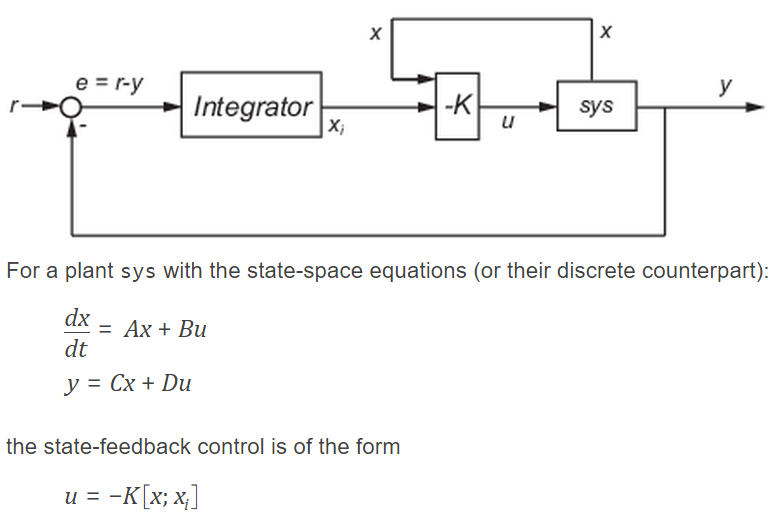

Note that:  

- 
$$K\in R^{N_u \times \left(N_x +N_y \right)}$$


Nx = size(A,1);  Nu = size(B,2);  Ny = size(C,1);

Now design a full state feedback controller using `LQI()`. NOTE the following:

- you will need to experiment with the Q,R weighting matrices

tmp = 1e2*[ones(1, Nx+Ny)];
Q   = diag(tmp); 
tmp = 1e4*[1,1,1,1];
R = diag(tmp); 

[K,~,~] = lqi(NEW_LIN_PLANT,Q,R,[])

What does the gain matrix K, look like?

hfig = figure;
% colormap(hfig,jet)
% imagesc(K); colorbar
heatmap(K,'ColorMap', jet(50) );

What do the closed loop poles look like ?

A_hat = [  A,   zeros(Nx,Ny);
          -C,   zeros(Ny,Ny) ];
      
B_hat = [ B;
          zeros(Ny,Nu) ];
p_lqi = esort( pole( ss((A_hat-B_hat*K),[],[],[]) ) )
